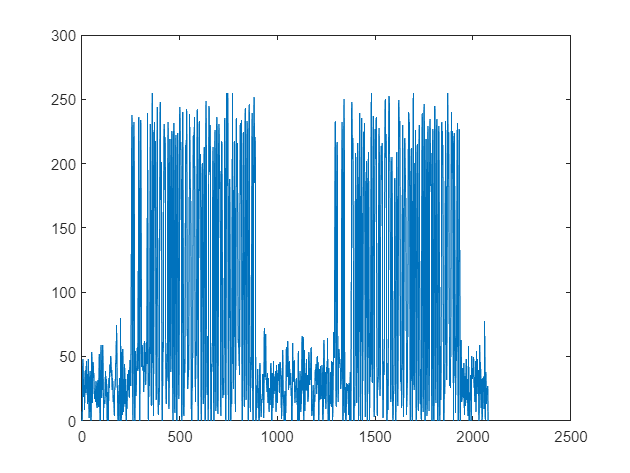

%Irasyti sugeneruota signala i txt faila generavimui
clear
data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
packet_bits = GenerateBits(data_binary);
data_binary2 = [0 1 0 0 0 0 0 1 1 1 0 0 0 1 0 0 1 0 1 0 1 1 0 0 0 1 0 0 1 0 1 1]';
packet_bits2 = GenerateBits(data_binary2);
signal_strength = 1;
[idealSignal1, noisySignal1, discretizedSignal1, ADCsignal1, ADCpreambule1] = GenerateSignal(packet_bits, signal_strength);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(packet_bits2, signal_strength);
signalaIrasyti = [ADCsignal1, ADCsignal2];

all_ideal = [idealSignal1, idealSignal2];
all_noisy = [noisySignal1, noisySignal2];
all_discretized = [discretizedSignal1, discretizedSignal2];
all_adc = [ADCsignal1, ADCsignal2];
all_preambule = [ADCpreambule1, ADCpreambule2];

plot(signalaIrasyti)


%Bandom csv
testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(signalaIrasyti)
    temp = dec2bin(signalaIrasyti(i), 10);
    fprintf(testVoltage,'%s\n',temp);
end
fclose(testVoltage);

save("TestVoltage.mat", "ADCpreambule1", "ADCpreambule2", "all_ideal", "all_noisy", ...
    "all_discretized", "all_adc", "all_preambule")